# First Order Ordinary Linear Systems : Sketch and Solve

% % Construct the domain
% t = pi/20 : pi/20 : 2*pi;
% Omega = polyshape({1.5*cos(t), 0.5+0.5*cos(t), 0.5+0.2*cos(t), -0.6+0.3*cos(t)}, ...
%                   {1.5*sin(t), 0.5*sin(t), 1+0.2*sin(t), -0.8+0.3*sin(t)});  % Omega
% 
% % Sloution Benchmark: poisson
% m  = 3 ;  % number of dependent variables
% u  = @(x,y) [sin(x.^2 + y.^2);  2*x.*cos(x.^2 + y.^2); 2*y.*cos(x.^2 + y.^2)];
% Dx_u = @(x,y) [2*x.*cos(x.^2 + y.^2);  2*cos(x.^2 + y.^2) - 4*x.^2.*sin(x.^2 + y.^2); -4*x.*y.*sin(x.^2 + y.^2)];
% Dy_u = @(x,y) [2*y.*cos(x.^2 + y.^2);  -4*x.*y.*sin(x.^2 + y.^2); 2*cos(x.^2 + y.^2) - 4*y.^2.*sin(x.^2 + y.^2)];
% 
% % System Settings
% num_eq = 4;
% A1 = @(x,y) [1,0,0; 0,0,0; 0,-1,0; 0,0,1];
% A2 = @(x,y) [0,0,0; 1,0,0; 0,0,-1; 0,-1,0];
% A0 = @(x,y) [0,-1,0; 0,0,-1; 0,0,0; 0,0,0];
% f  = @(x,y) [0 ; 0; - 4*cos(x.^2 + y.^2) + 4*(x.^2 + y.^2).*sin(x.^2 + y.^2); 0];
% 
% % Sample Equation
% beta = 5 ; hmax = 0.2 ;   % mesh size, hmin=hmax/beta 
% model = Collocation2D(m, Omega);           % Construct the model
% model.discretize(hmax, beta, 'linear');    % Discretization
% if true 
%     model.gm.pdemesh(); %(ElementLabels="on", NodeLabels="on") ;
%     hold on
%     edge = model.boundary_decompose();
%     for i = 1:model.gm.NumEdges
%         scatter(edge{i}(1:end-1,1), edge{i}(1:end-1,2), "filled")
%     end
%     hold off
%     fprintf('%d Nodes (%d unknowns) and %d Elements generated', size(model.gm.Mesh.Nodes,2), ...
%             size(model.gm.Mesh.Nodes,2)*m, size(model.gm.Mesh.Elements,2));
% end

% % Condition Settings
% num_cond = 2; B1 = []; B2 = [];
% B0 = @(x,y) [1,0,0; 0, model.boundary_normal([x,y], 2), -model.boundary_normal([x,y], 1)];
% g1 = @(x,y) sin(x.^2 + y.^2);
% g2 = @(x,y) model.boundary_normal([x,y]) * [-2*y.*cos(x.^2 + y.^2); 2*x.*cos(x.^2 + y.^2)];
% g  = @(x,y) [g1(x,y); g2(x,y)];
% 
% % Construct the model
% model.fitInterior(A1, A2, A0, f, num_eq);
% model.fitBoundary(B1, B2, B0, g, num_cond);
% model.fitTrueSol(u, Dx_u, Dy_u);
% 
% % Coordinates of the closed boundary nodes
% rng(42) ;  % random seed
% N_loc = max( ceil((1/hmax.^4)/(size(model.gm.Mesh.Elements,2))), 8);
% N_Gamma = max(ceil(1/hmax.^2), cellfun(@(x)size(x,1), model.Edges)) ;
% sampled_interior_nodes = model.sample_from_triangleMesh(model.gm.Mesh, N_loc);
% sampled_boundary_nodes = model.interp_multiedge_polyboundary(model.Edges, num2cell(N_Gamma));
% 
% N_Omega = size(sampled_interior_nodes, 1); N_Gamma = size(sampled_boundary_nodes, 1);
% fprintf('N_Omega: %d, N_Gamma: %d, total: %d', N_Omega, N_Gamma, N_Omega + N_Gamma);
% fprintf('eq_Omega: %d, eq_Gamma: %d, eq_total: %d', N_Omega*num_eq, N_Gamma*num_cond, N_Omega*num_eq + N_Gamma*num_cond);
% 
% % System assemble
% Lambda = eye(num_cond)*(hmax^(-3/2));     % square(weights) for BC
% [B_Omega, d_Omega, N_Omega] = model.Assemble_B_Omega(sampled_interior_nodes);
% [B_Gamma, d_Gamma, N_Gamma] = model.Assemble_B_Gamma(sampled_boundary_nodes, Lambda);
% B = [B_Omega ; B_Gamma];  d = [d_Omega ; d_Gamma];
% 
% fprintf('eq_Omega: %d, eq_Gamma: %d, eq_total: %d', N_Omega*num_eq, N_Gamma*num_cond, N_Omega*num_eq + N_Gamma*num_cond);
% fprintf('num_eq: %d, num_unknown: %d, ratio m/n: %.2f', size(B,1), size(B,2), size(B,1)/size(B,2));
% spy(B); c = B\d; model.C = model.reshape2mat(c);
% save('./data/2DconvSample/2DconvSampleModel7.mat', 'model');

% load('./data/1D_SketchAndSolve_CollocationExample_01.mat');
addpath('./Skechers/');
data = {'./data/2DconvSample/2DconvSampleModel1.mat';
        './data/2DconvSample/2DconvSampleModel2.mat';
        './data/2DconvSample/2DconvSampleModel3.mat';
        './data/2DconvSample/2DconvSampleModel4.mat';
        './data/2DconvSample/2DconvSampleModel5.mat';
        './data/2DconvSample/2DconvSampleModel6.mat';
        './data/2DconvSample/2DconvSampleModel7.mat'};

% Construct the model
load('./data/2DconvSample/2DconvSampleModel_stat.mat')
h = [0.05, 0.075, 0.1, 0.125, 0.15, 0.175, 0.2]; num_sample = length(h);
skt_coe = 4; rng(42); num_coworker = 50;

for j = 1:num_sample
    fprintf("Sample %d starts : ", j); load(data{j});
    B_Omega = model.Omega_assemble.B; d_Omega = model.Omega_assemble.d;
    B_Gamma = model.Gamma_assemble.B; d_Gamma = model.Gamma_assemble.d;
    B = [B_Omega ; B_Gamma]; d = [d_Omega ; d_Gamma]; [~, nB] = size(B_Omega);
    mS = skt_coe * nB;
    
    origin = struct(); 
    origin.L2 = model.Hk_error([], 0);
    origin.H1 = model.Hk_error([], 1);
    origin.res = norm(B*reshape(model.C,[],1)-d);
    origin.sigmaB = svds(B, 1, 'smallest');
    origin.cond = svds(B, 1)/origin.sigmaB;
    sample{13,j} = origin;
    % origin = sample{13,j};

    for i = 1:12
        fprintf("Sample %d starts : %d/12\n", j, i);
        sketcher = struct(); 

        switch i
            case 1
                if j ~= 1
                    [SBd, ~] = sketching(mS, [B_Omega, d_Omega], 'Gaussian');
                else
                    sample{i,j} = struct();
                    continue
                end

            case 2
                [SBd, ~] = sketching(mS, [B_Omega, d_Omega], 'Hashing', {1, 'Regular'});

            case 3
                s = ceil(log(nB));
                [SBd, ~] = sketching(mS, [B_Omega, d_Omega], 'Hashing', {s, 'Regular'});

            case 4
                if j ~= 1
                    [lev_score, ~, ~] = leverageScore(B_Omega,'Exact','svd');
                    p = lev_score./sum(lev_score);
                    [SBd, ~] = sketching(mS, [B_Omega, d_Omega], 'Levscore', p);
                else
                    sample{i,j} = struct();
                    continue
                end

            case 5
                if j ~= 1
                    [lev_score, ~, ~] = leverageScore(B_Omega,'Approx','svd');
                    p = lev_score./sum(lev_score);
                    [SBd, ~] = sketching(mS, [B_Omega, d_Omega], 'Levscore', p);
                else
                    sample{i,j} = struct();
                    continue
                end

            case 6
                if j ~= 1
                    [lev_score, ~, ~] = leverageScore(B_Omega,'Hashing_Approx','svd');
                    p = lev_score./sum(lev_score);
                    [SBd, ~] = sketching(mS, [B_Omega, d_Omega], 'Levscore', p);
                else
                    sample{i,j} = struct();
                    continue
                end

            case 7
                [SBd, ~] = blockEmbedding(mS, [B_Omega, d_Omega], num_coworker, 'Gaussian');
            case 8
                [SBd, ~] = blockEmbedding(mS, [B_Omega, d_Omega], num_coworker, 'Hashing', {1, 'Regular'});
            case 9
                s = ceil(log(nB));
                [SBd, ~] = blockEmbedding(mS, [B_Omega, d_Omega], num_coworker, 'Hashing', {s, 'Regular'});  
            case 10
                [SBd, ~] = blockEmbedding(mS, [B_Omega, d_Omega], num_coworker, 'Levscore', {'Exact','svd'});
            case 11
                [SBd, ~] = blockEmbedding(mS, [B_Omega, d_Omega], num_coworker, 'Levscore', {'Approx','svd'});
            case 12
                [SBd, ~] = blockEmbedding(mS, [B_Omega, d_Omega], num_coworker, 'Levscore', {'Hashing_Approx','svd'});
        end

        SBd = [SBd; [B_Gamma, d_Gamma]]; 
        SB = SBd(:,1:end-1); Sd = SBd(:,end);
        sketcher.sol = SB\Sd;
        Cskt = model.reshape2mat(sketcher.sol);
        sketcher.L2 = model.Hk_error(Cskt, 0);
        sketcher.H1 = model.Hk_error(Cskt, 1);
        sketcher.error = norm(sketcher.sol-reshape(model.C,[],1));
        sketcher.res = norm(B*sketcher.sol-d);
        sketcher.k = (sketcher.res ./ origin.res).^2;
        sketcher.epsilon = (sketcher.k-1)/(sketcher.k+1);
        sketcher.error_bound = (origin.res./origin.sigmaB) * (1+sqrt((1+sketcher.epsilon)/(1-sketcher.epsilon)));

        sketcher.sigmaB = svds(SB, 1, 'smallest');
        % sketcher.cond = svds(SB,1)/sketcher.sigmaB;
        sample{i,j} = sketcher;
    end
    % save('./data/2DconvSample/2DconvSampleModel_stat.mat', 'sample');
end

Sample 2 starts : 

Sample 2 starts : 4/12
Sample 2 starts : 5/12
Sample 2 starts : 6/12
Sample 2 starts : 10/12
Sample 2 starts : 11/12
Sample 2 starts : 12/12


Sample 3 starts : 

Sample 3 starts : 4/12
Sample 3 starts : 5/12
Sample 3 starts : 6/12
Sample 3 starts : 10/12
Sample 3 starts : 11/12
Sample 3 starts : 12/12


Sample 4 starts : 

Sample 4 starts : 4/12
Sample 4 starts : 5/12
Sample 4 starts : 6/12
Sample 4 starts : 10/12
Sample 4 starts : 11/12
Sample 4 starts : 12/12


Sample 5 starts : 

Sample 5 starts : 4/12
Sample 5 starts : 5/12
Sample 5 starts : 6/12
Sample 5 starts : 10/12
Sample 5 starts : 11/12
Sample 5 starts : 12/12


Sample 6 starts : 

Sample 6 starts : 4/12
Sample 6 starts : 5/12
Sample 6 starts : 6/12
Sample 6 starts : 10/12
Sample 6 starts : 11/12
Sample 6 starts : 12/12


Sample 7 starts : 

Sample 7 starts : 4/12
Sample 7 starts : 5/12
Sample 7 starts : 6/12
Sample 7 starts : 10/12
Sample 7 starts : 11/12
Sample 7 starts : 12/12


% load('./data/2DconvSample/2DconvSampleModel_stat.mat')
% for j = 1:6
%     for i = 1:12
%         res = sample{13,j}.res;
%         sigmaB = sample{13,j}.sigmaB;
%         if (j == 1) && (ismember(i,[1,4,5,6]))
%             continue
%         else
%             sample{i,j}.cond = nan;
%         end
%     end
% end
% save('./data/2DconvSample/2DconvSampleModel_stat.mat', 'sample');

load('./data/2DconvSample/2DconvSampleModel_stat.mat')
h = [0.05, 0.075, 0.1, 0.125, 0.15, 0.175, 0.2];
color = [0.6350,  0.0780,  0.1840; 
         0.8500,  0.3250,  0.0980; 
         247/255, 152/255, 36/255; 
         30/255,  70/255,  110/255;
         45/255, 106/255, 79/255];

face_color = [238, 115, 125; 
              244, 169, 97; 
              255, 226, 84; 
              78,  127, 196;
              118, 200, 147]./255;

cellfun(@(x) x.ratio,sample(13,:))

ans =     78    34    19    19    18    18    17


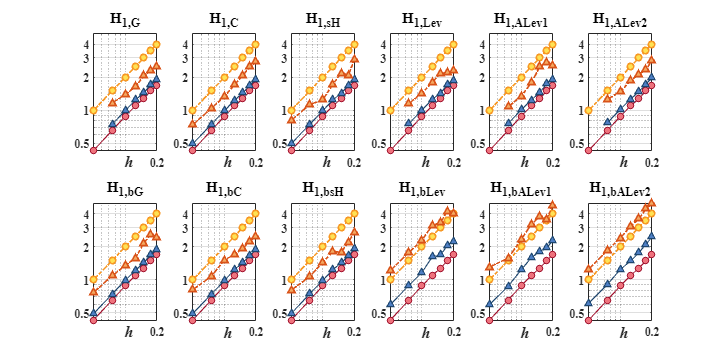

% Plot Error
H1 = cellfun(@(x) x.H1,sample(13,:));
figure; set(gcf,'position',[0, 0, 900, 450]); tiledlayout(2,6); 
Htitles = {'H_{1,G}', 'H_{1,C}',   'H_{1,sH}',  'H_{1,Lev}',  'H_{1,ALev1}',  'H_{1,ALev2}',...
           'H_{1,bG}', 'H_{1,bC}', 'H_{1,bsH}', 'H_{1,bLev}', 'H_{1,bALev1}', 'H_{1,bALev2}'};

for i = 1:12
    nexttile(i);
    if ismember(i,[1,4,5,6])
        plotdata = cellfun(@(x) x.H1, sample(i,2:end));
        plotdata = [nan,plotdata];
        plotdata2 = cellfun(@(x) x.error, sample(i,2:end));
        plotdata2 = [nan,plotdata2];
    else
        plotdata = cellfun(@(x) x.H1, sample(i,:));
        plotdata2 = cellfun(@(x) x.error, sample(i,:));
    end

    loglog(h, H1, '-o', 'Color', color(1,:), 'LineWidth', 1, 'MarkerFaceColor', face_color(1,:)); 
    hold on; grid on; box on;
    loglog(h, 20*h,  '-.o', 'Color', color(3,:), 'LineWidth', 1.5, 'MarkerFaceColor', face_color(3,:)); 
    loglog(h, plotdata, '-^', 'Color', color(4,:), 'LineWidth', 1, 'MarkerFaceColor', face_color(4,:)); 
    loglog(h, 3.7*plotdata2, '-.^', 'Color', color(2,:), 'LineWidth', 1.5, 'MarkerFaceColor', face_color(2,:)); 

    xticks([0 0.2]); 
    ylim([0, 5]); yticks([0.5,1,2,3,4]);
    set(gca,'fontname','times','FontWeight','Bold'); ax = gca; ax.FontSize = 11;
    xh = xlabel("\it h",'FontSize', 15, 'FontWeight', 'bold');
    xh.Position(2) = xh.Position(2) + 0.109;
    title(Htitles{i},'fontweight','bold','FontSize',14);
end

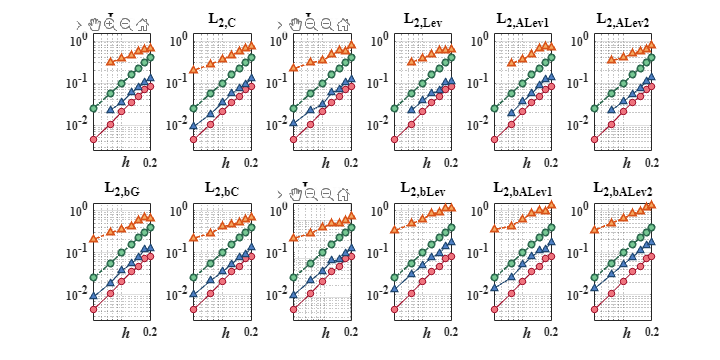

L2 = cellfun(@(x) x.L2,sample(13,:));
figure; set(gcf,'position',[0, 0, 900, 450]); tiledlayout(2,6); 
Ltitles = {'L_{2,G}', 'L_{2,C}', 'L_{2,sH}', 'L_{2,Lev}',  'L_{2,ALev1}',  'L_{2,ALev2}',...
           'L_{2,bG}', 'L_{2,bC}', 'L_{2,bsH}', 'L_{2,bLev}', 'L_{2,bALev1}', 'L_{2,bALev2}'};

for i = 1:12
    nexttile(i);
    if ismember(i,[1,4,5,6])
        plotdata = cellfun(@(x) x.L2, sample(i,2:end));
        plotdata = [nan,plotdata];
        plotdata2 = cellfun(@(x) x.error, sample(i,2:end));
        plotdata2 = [nan,plotdata2];
    else
        plotdata = cellfun(@(x) x.L2, sample(i,:));
        plotdata2 = cellfun(@(x) x.error, sample(i,:));
    end

    loglog(h, L2, '-o', 'Color', color(1,:), 'LineWidth', 1, 'MarkerFaceColor', face_color(1,:)); 
    hold on; grid on; box on;
    loglog(h, 10*h.^2,  '-.o', 'Color', color(5,:), 'LineWidth', 1.5, 'MarkerFaceColor', face_color(5,:)); 
    loglog(h, plotdata, '-^', 'Color', color(4,:), 'LineWidth', 1, 'MarkerFaceColor', face_color(4,:)); 
    loglog(h, plotdata2, '-.^', 'Color', color(2,:), 'LineWidth', 1.5, 'MarkerFaceColor', face_color(2,:)); 

    xticks([0 0.2]);
    ylim([2.5e-3 1.5]); yticks([0.01, 0.1, 1]);
    set(gca,'fontname','times','FontWeight','Bold'); ax = gca; ax.FontSize = 11;
    xh = xlabel("\it h",'FontSize', 15, 'FontWeight', 'bold');
    xh.Position(2) = xh.Position(2) + 0.0011;
    title(Ltitles{i},'fontweight','bold','FontSize',14);
end

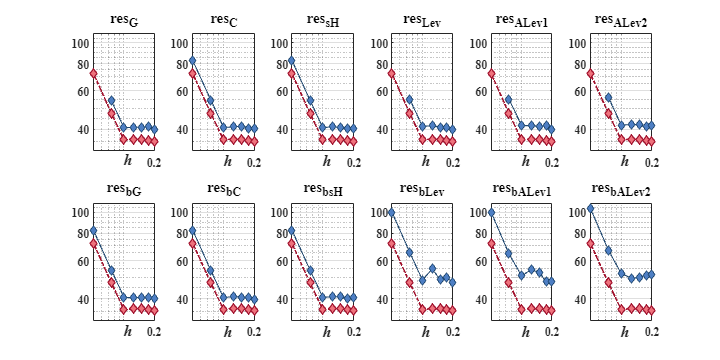

% Plot Skt Error
res = cellfun(@(x) x.res,sample(13,:));
figure; set(gcf,'position',[0, 0, 900, 450]); tiledlayout(2,6); 
restitles = {'res_{G}', 'res_{C}', 'res_{sH}', 'res_{Lev}',  'res_{ALev1}',  'res_{ALev2}',...
             'res_{bG}', 'res_{bC}', 'res_{bsH}', 'res_{bLev}', 'res_{bALev1}', 'res_{bALev2}'};


for i = 1:12
    nexttile(i);
    if ismember(i,[1,4,5,6])
        plotdata = cellfun(@(x) x.res, sample(i,2:end));
        plotdata = [nan,plotdata];
    else
        plotdata = cellfun(@(x) x.res, sample(i,:));
    end


    loglog(h, res, '-.diamond', 'Color', color(1,:), 'LineWidth', 1.5, 'MarkerFaceColor', face_color(1,:)); 
    hold on; grid on; box on;
    loglog(h, plotdata, '-diamond', 'Color', color(4,:), 'LineWidth', 1, 'MarkerFaceColor', face_color(4,:)); 

    xticks([0 0.2]); ylim([32, 110]); 
    set(gca,'fontname','times','FontWeight','Bold'); ax = gca; ax.FontSize = 11;
    xh = xlabel("\it h",'FontSize', 15, 'FontWeight', 'bold');
    xh.Position(2) = xh.Position(2) + 5;
    title(restitles{i},'fontweight','bold','FontSize',14);
end

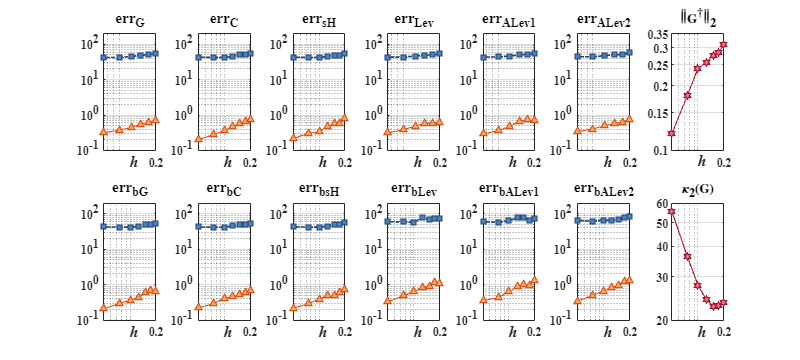

sigB = cellfun(@(x) x.sigmaB, sample(13,:));
cond = cellfun(@(x) x.cond, sample(13,:));
figure; set(gcf,'position',[0, 0, 1000, 450]); tiledlayout(2,7); 
errtitles = {'err_{G}', 'err_{C}', 'err_{sH}', 'err_{Lev}',  'err_{ALev1}',  'err_{ALev2}',...
             'err_{bG}', 'err_{bC}', 'err_{bsH}', 'err_{bLev}', 'err_{bALev1}', 'err_{bALev2}'};

for i = 1:12
    if i >= 7
        nexttile(i+1);
    else
        nexttile(i);
    end
    
    if ismember(i,[1,4,5,6])
        plotdata = cellfun(@(x) x.error, sample(i,2:end));
        plotdata = [nan,plotdata];
        plotdata2 = cellfun(@(x) x.error_bound, sample(i,2:end));
        plotdata2 = [nan,plotdata2];
    else
        plotdata = cellfun(@(x) x.error, sample(i,:));
        plotdata2 = cellfun(@(x) x.error_bound, sample(i,:));
    end

    loglog(h, plotdata, '-^', 'Color', color(2,:), 'LineWidth', 1, 'MarkerFaceColor', face_color(2,:));
    hold on; grid on; box on;
    loglog(h, plotdata2, '-.square', 'Color', color(4,:), 'LineWidth', 1.5, 'MarkerFaceColor', face_color(4,:)); 

    xticks([0 0.2]);
    ylim([1e-1 200]); yticks([0.1,1,10,100]);
    set(gca,'fontname','times','FontWeight','Bold'); ax = gca; ax.FontSize = 11;
    xh = xlabel("\it h",'FontSize', 15, 'FontWeight', 'bold');
    xh.Position(2) = xh.Position(2) + 0.05;
    title(errtitles{i},'fontweight','bold','FontSize',14);

end

nexttile(7);
loglog(h, 1./sigB, '-hexagram', 'Color', color(1,:), 'LineWidth', 1, 'MarkerSize', 7, 'MarkerFaceColor', face_color(1,:)); 
grid on; box on; xticks([0 0.2]);
ylim([0.1, 0.35]); yticks([0.1 0.15, 0.2, 0.25, 0.3, 0.35]);
set(gca,'fontname','times','FontWeight','Bold'); ax = gca; ax.FontSize = 11;
xh = xlabel("\it h",'FontSize', 15, 'FontWeight', 'bold');
th = title('$\mathbf{\left \|  G^{\dagger}\right \|_2}$','Interpreter','latex');
xh.Position(2) = xh.Position(2) + 0.018;

nexttile(14);
loglog(h, cond, '-hexagram', 'Color', color(1,:), 'LineWidth', 1, 'MarkerSize', 7, 'MarkerFaceColor', face_color(1,:)); 
grid on; box on; xticks([0 0.2]); 
ylim([20, 60]); yticks([20,30,40,50,60]); 
set(gca,'fontname','times','FontWeight','Bold'); ax = gca; ax.FontSize = 11;
xh = xlabel("\it h",'FontSize', 15, 'FontWeight', 'bold');
xh.Position(2) = xh.Position(2) + 2.7;
title('$\mathbf{\kappa_2(G)}$','Interpreter','latex');